# How to use MatLab to solve 2x2 Matrices with node voltage analysis

Arielle Blum

Solve for the node voltages VA & VB, using Is and resistors

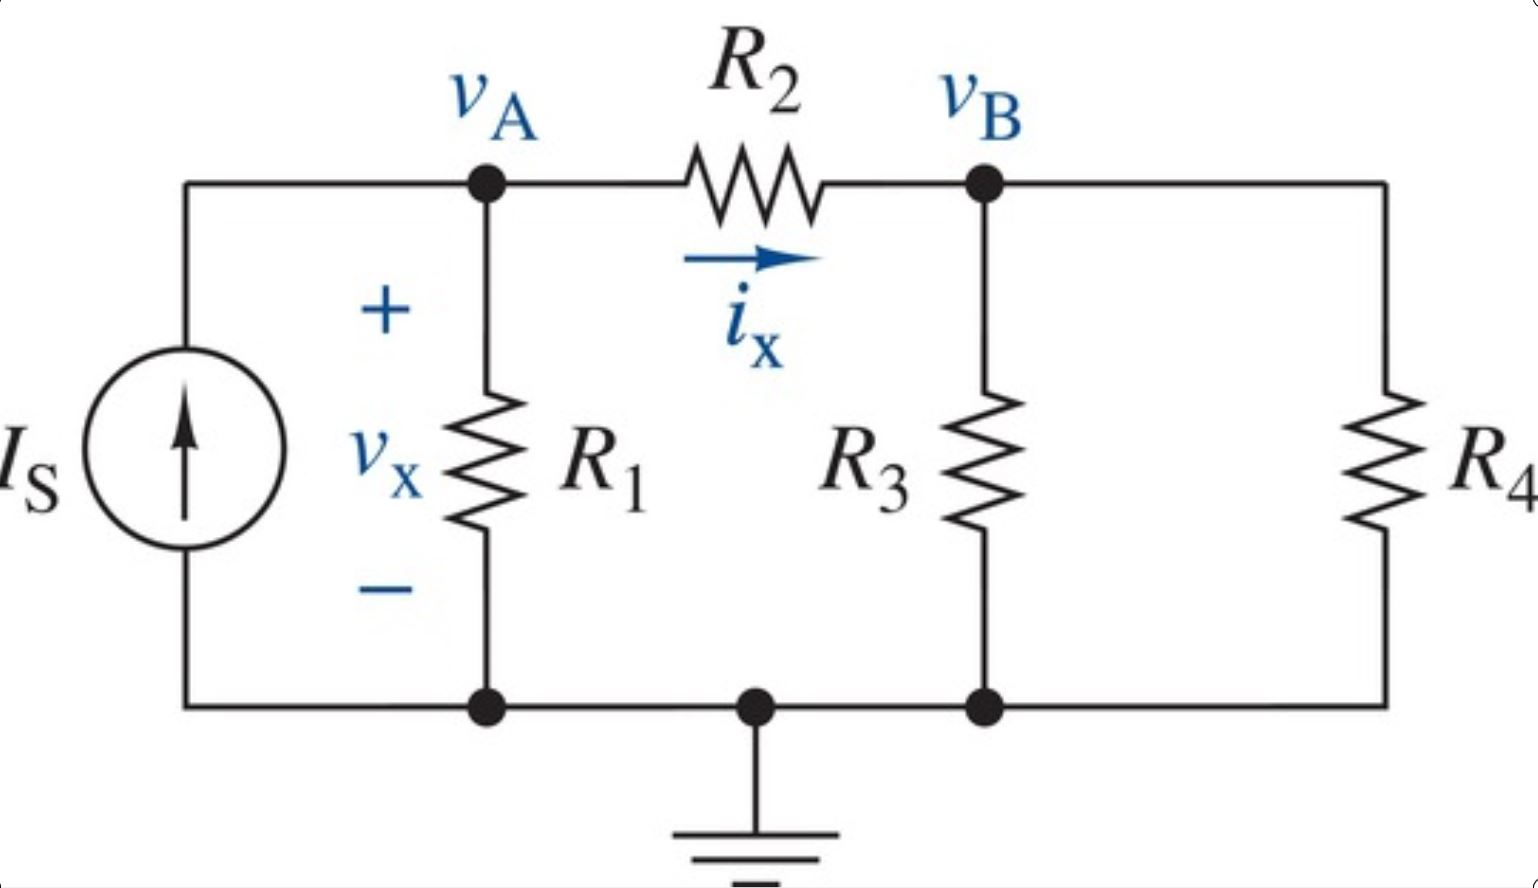

clc

Define symbolic variables

syms Is real
syms R1 R2 R3 R4 positive

Create A Matrix which is the Admittance Matrix (1/R)

A = [((1/R1)+(1/R2)), (-1/R2); (-1/R2), ((1/R2)+(1/R3)+(1/R4))]

$$A = \left(\begin{array}{cc} \frac{1}{R_{1}}+\frac{1}{R_{2}} & -\frac{1}{R_{2}}\\ -\frac{1}{R_{2}} & \frac{1}{R_{2}}+\frac{1}{R_{3}}+\frac{1}{R_{4}} \end{array}\right)$$

Set up b matrix

b = [Is; 0]

$$b = \left(\begin{array}{c} \mathrm{Is}\\ 0 \end{array}\right)$$

Solve for the node voltages

x = A\b

$$x = \left(\begin{array}{c} \frac{\mathrm{Is}\,R_{1}\,\left(R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}\right)}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}\\ \frac{\mathrm{Is}\,R_{1}\,R_{3}\,R_{4}}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}} \end{array}\right)$$

Assign to node voltages VA and VB

VA = x(1)

$$VA = \frac{\mathrm{Is}\,R_{1}\,\left(R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}\right)}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}$$

VB = x(2)

$$VB = \frac{\mathrm{Is}\,R_{1}\,R_{3}\,R_{4}}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}$$

Given Vx = VA & Ix = (VA-VB)/R2

Vx = simplify(VA)

$$Vx = \frac{\mathrm{Is}\,R_{1}\,\left(R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}\right)}{R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}}$$

Ix = simplify(Vx/R2)

$$Ix = \frac{\mathrm{Is}\,R_{1}\,\left(R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}\right)}{R_{2}\,\left(R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}+R_{3}\,R_{4}\right)}$$